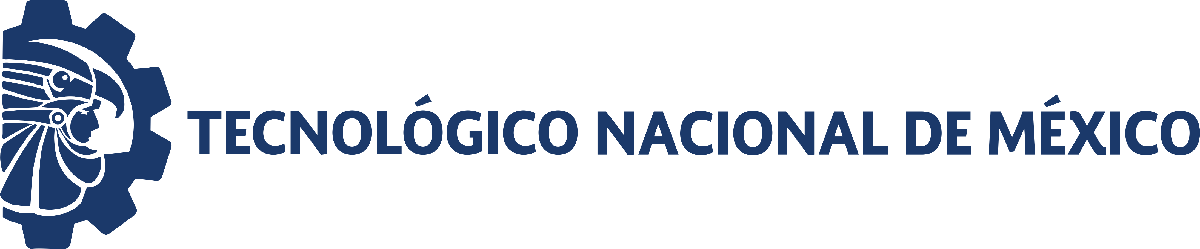                                 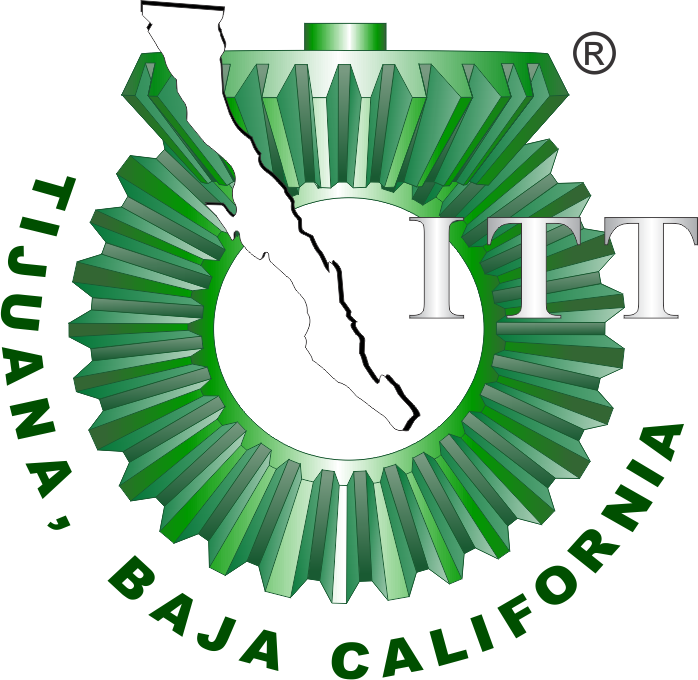

# Práctica tres: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

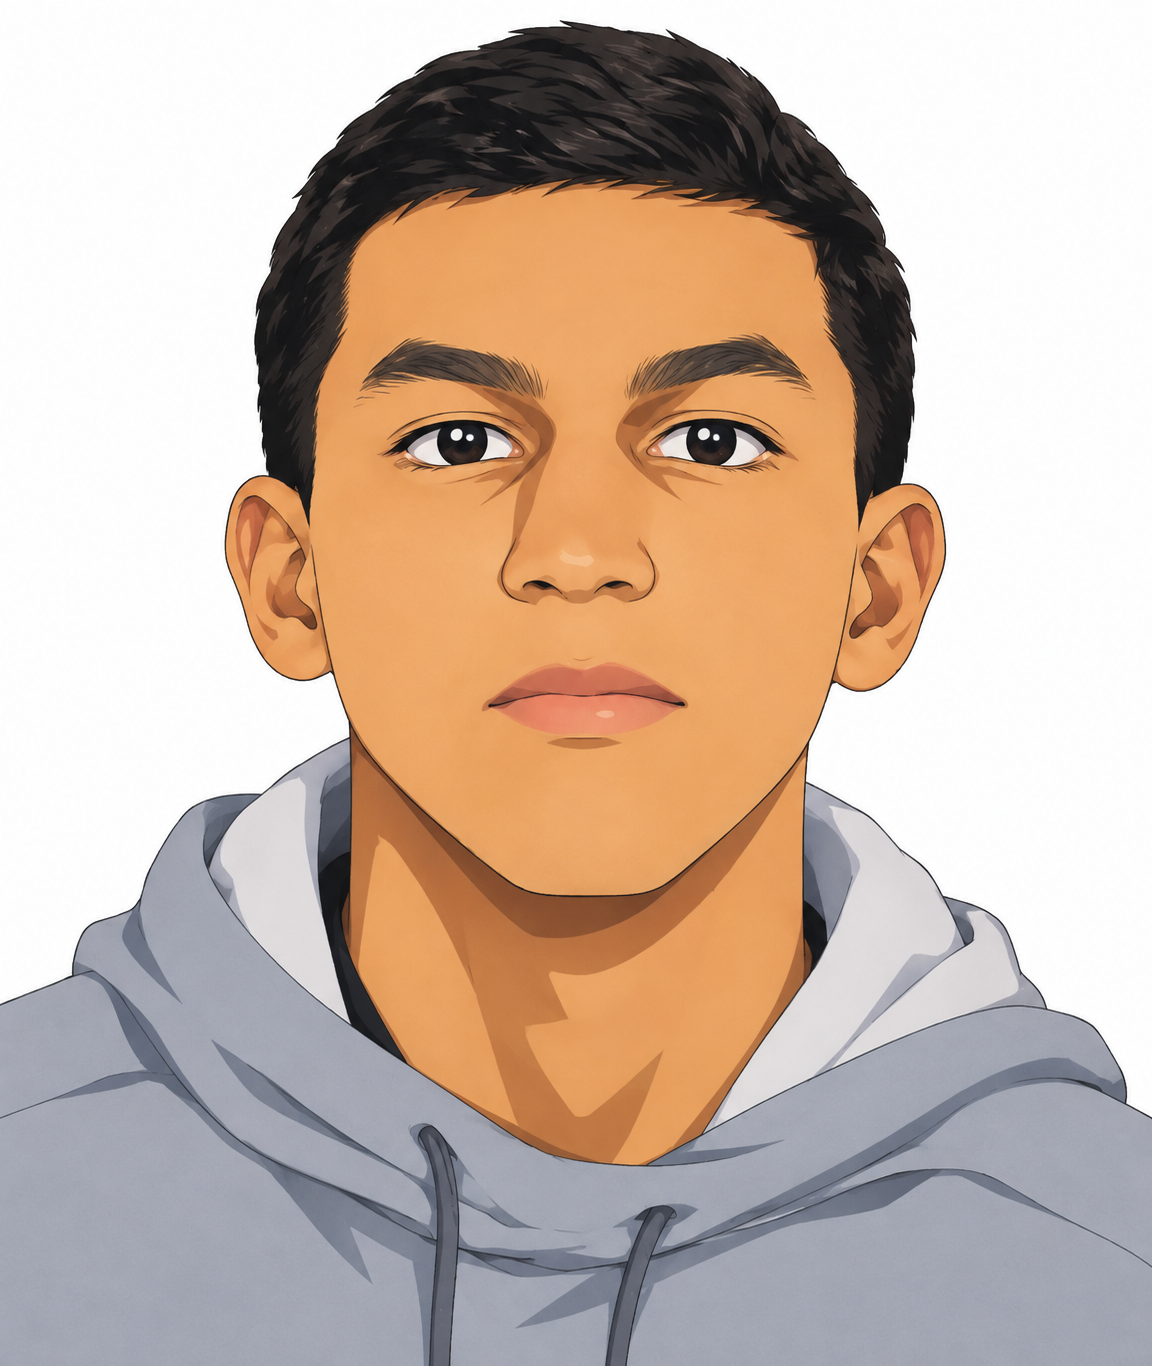

Nombre del alumno: **Sergio Andree Navarro Rodriguez**

Número de control: **23212219**

Correo institucional:** l23212219@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('unidad4')
parameters.StopTime='15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## CONTROL,CASO,TRATAMIENTO

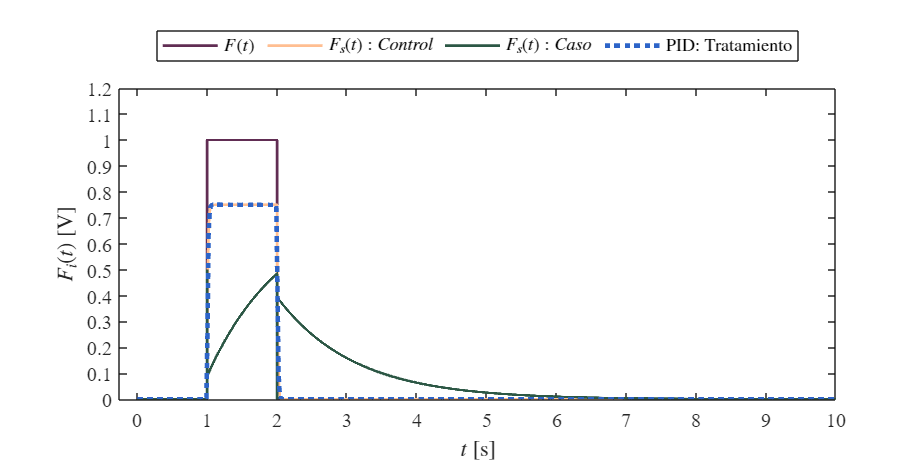

x = sim('unidad4.slx',parameters);
plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID)

## Función: Respuestas de la simulacion

function plotsignals(t,F,Fsx,Fsy,PID)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = [97,45,83]/255;
clr2 = [255,190,145]/255;
clr3 = [44,87,69]/255;
clr4 = [45,100,200]/255;
plot(t,F,'-','Linewidth',1.5,'Color',clr1)
plot(t,Fsx,'-','Linewidth',1.5,'Color',clr2)
plot(t,Fsy,'-','Linewidth',1.5,'Color',clr3)
plot(t,PID,':','Linewidth',2.5,'Color',clr4)
L = legend('$F(t)$','$F_{s}(t):Control$','$F_{s}(t):Caso$','PID: Tratamiento');
set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
xlabel('$t$ [s]','interpreter','latex')
ylabel('$F_i (t)$ [V]','interpreter','latex')
xlim([-0.25 10]); xticks(0:1:10)
ylim([0 1.2]); yticks(0:0.1:1.2)
exportgraphics(gcf,'_matlab.pdf','ContentType','vector')
end